load mystery_song.mat

theVoices.noteNumbers

ans =     36
    38
    41
    38
    45
    45
    43
    36
    38
    40


theVoices.startPulses;
theVoices.durations

ans =      1
     1
     1
     1
     3
     3
     6
     1
     1
     1


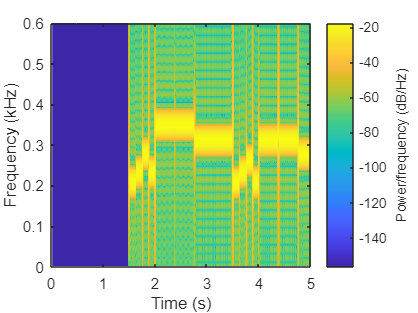


bpm = 120;
beats_per_second = bpm/60;
seconds_per_beat = 1/beats_per_second;
seconds_per_pulse = seconds_per_beat/4;
fs = 22050;

tt = [0:1/fs:250*seconds_per_pulse];
xx = zeros(size(tt));

for idx = 1:length(theVoices.startPulses)
    tone = key2note(1,theVoices.noteNumbers(idx),theVoices.durations(idx)*seconds_per_pulse,fs);
    xxstart = ceil((theVoices.startPulses(idx)-1)*seconds_per_pulse*fs)+1;
    xxstop = xxstart + length(tone)-1;
    xx(xxstart:xxstop) = xx(xxstart:xxstop) + tone;
end

spectrogram(xx(1:120000),1024,800,16384,22050,'yaxis')
xlim([0,5])
ylim([0,0.6])

%soundsc( xx, fs )